# COCOAN 101: Lecture 12 - Network analysis

## Basic Setting

basedir = '/Users/jaejoonglee/Dropbox/Presentations/Lecture/2021_cocoan101'; % Change this path
bctdir = '/Users/jaejoonglee/Resource/fmri_toolboxes/BCT';
addpath(genpath(bctdir));
load(fullfile(basedir, 'Cocoan101_L12_data_ROI_meants.mat'), '*_roi_meants');
atlas_img = fmri_data(which('Fan_et_al_atlas_r279_MNI.nii'));

Using default mask: /Users/jaejoonglee/github/canlab/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
Direct calls to spm_defauts are deprecated.
Please use spm('Defaults',modality) or spm_get_defaults instead.
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 971812 bytes
Loading image number:     1
경과 시간은 0.057095초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


atlas_info = load(which('cluster_Fan_Net_r279.mat'));

## Network attributes

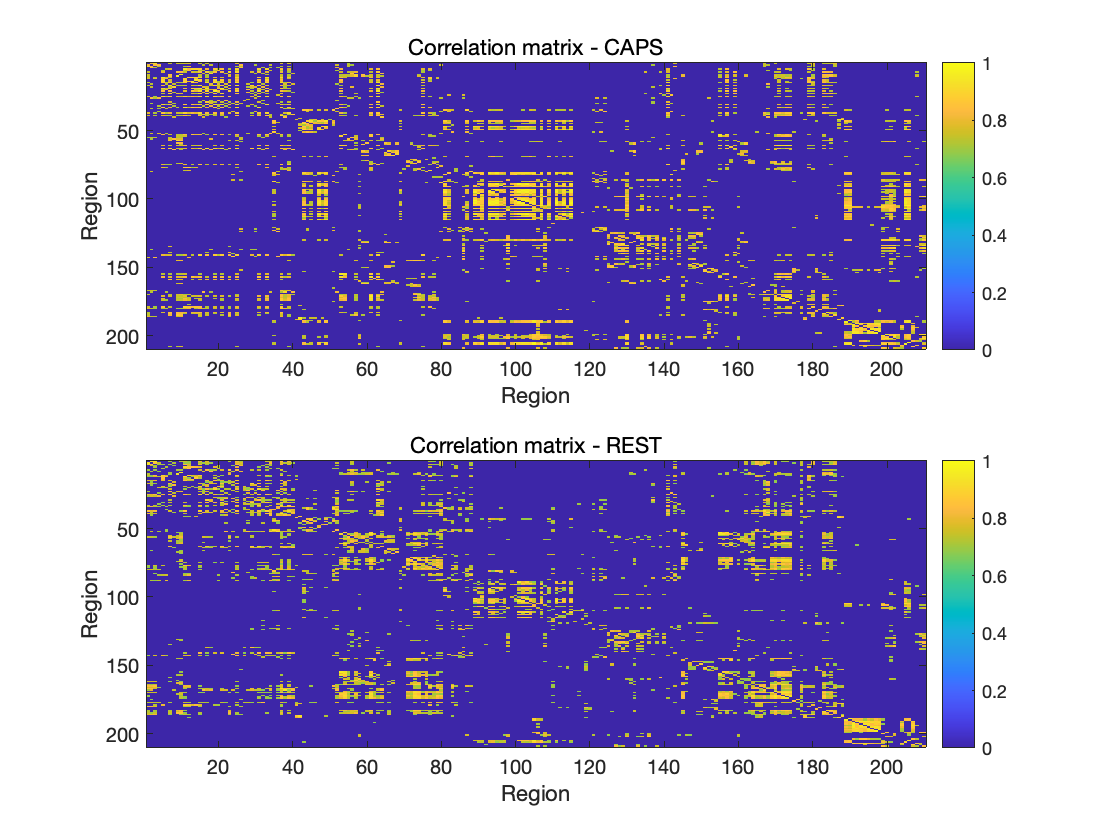

sj_num = 18;
CAPS_r = corr(CAPS_roi_meants{sj_num}(:,1:210));
REST_r = corr(REST_roi_meants{sj_num}(:,1:210));
CAPS_thr_r = threshold_proportional(CAPS_r, 0.1);
REST_thr_r = threshold_proportional(REST_r, 0.1);

figure;
subplot 211; imagesc(CAPS_thr_r, [0 1]); colorbar; title('Correlation matrix - CAPS'); xlabel('Region'); ylabel('Region');
subplot 212; imagesc(REST_thr_r, [0 1]); colorbar; title('Correlation matrix - REST'); xlabel('Region'); ylabel('Region');

% 1 & 2. characteristic path length (=average shortest path length),
% and global efficiency (=average inverse shortest path length)
CAPS_dist_r = distance_wei(weight_conversion(CAPS_thr_r, 'lengths'));
REST_dist_r = distance_wei(weight_conversion(REST_thr_r, 'lengths'));
[CAPS_N.characteristic_path, CAPS_N.global_efficiency,~,~,~] = charpath(CAPS_dist_r, 0, 0);
[REST_N.characteristic_path, REST_N.global_efficiency,~,~,~] = charpath(REST_dist_r, 0, 0);

% 3. clustering coefficient (node-level clustering coefficient)
CAPS_N.clustering_coefficient = mean(clustering_coef_wu(CAPS_thr_r));
REST_N.clustering_coefficient = mean(clustering_coef_wu(REST_thr_r));

% 4. transitivity (network-level clustering coefficient)
CAPS_N.transitivity = transitivity_wu(CAPS_thr_r);
REST_N.transitivity = transitivity_wu(REST_thr_r);

% 5. modularity
[CAPS_N.community_index, CAPS_N.modularity] = modularity_und(CAPS_thr_r);
[REST_N.community_index, REST_N.modularity] = modularity_und(REST_thr_r);
Ci_sorted = match_community_affiliation([CAPS_N.community_index, REST_N.community_index]);


Divergence found between time (or category) 1 and 2 ... 


REST_N.community_index = Ci_sorted(:,2);

% 6. assortativity
CAPS_N.assortativity = assortativity_wei(CAPS_thr_r, 0);
REST_N.assortativity = assortativity_wei(REST_thr_r, 0);

% null networks
n_null = 50;
for k = 1:n_null
    if mod(k, 10) == 0; fprintf('Working on repetition %d ... \n', k); end
    null_CAPS_thr_r = randmio_und(CAPS_thr_r, 5);
    null_REST_thr_r = randmio_und(REST_thr_r, 5);
    null_CAPS_dist_r = distance_wei(weight_conversion(null_CAPS_thr_r, 'lengths'));
    null_REST_dist_r = distance_wei(weight_conversion(null_REST_thr_r, 'lengths'));
    [CAPS_N.null_characteristic_path(k), CAPS_N.null_global_efficiency(k),~,~,~] = charpath(null_CAPS_dist_r, 0, 0);
    [REST_N.null_characteristic_path(k), REST_N.null_global_efficiency(k),~,~,~] = charpath(null_REST_dist_r, 0, 0);
    CAPS_N.null_clustering_coefficient(k) = mean(clustering_coef_wu(null_CAPS_thr_r));
    REST_N.null_clustering_coefficient(k) = mean(clustering_coef_wu(null_REST_thr_r));
end

Working on repetition 10 ... 
Working on repetition 20 ... 
Working on repetition 30 ... 
Working on repetition 40 ... 
Working on repetition 50 ... 


CAPS_N.small_worldness = (CAPS_N.clustering_coefficient / mean(CAPS_N.null_clustering_coefficient)) ./ (CAPS_N.characteristic_path / mean(CAPS_N.null_characteristic_path));
REST_N.small_worldness = (REST_N.clustering_coefficient / mean(REST_N.null_clustering_coefficient)) ./ (REST_N.characteristic_path / mean(REST_N.null_characteristic_path));

T = struct2table([CAPS_N REST_N]');
T.Properties.RowNames = {'CAPS', 'REST'};
disp(T)

            characteristic_path    global_efficiency    clustering_coefficient    transitivity    community_index    modularity    assortativity    null_characteristic_path    null_global_efficiency    null_clustering_coefficient    small_worldness
            ___________________    _________________    ______________________    ____________    _______________    __________    _____________    ________________________    ______________________    ___________________________    _______________

    CAPS          4.3159                 0.3041                0.48172              0.54848       {210×1 double}      0.56231         0.47597            [1×50 double]              [1×50 double]                [1×50 double]               1.8457     
    REST          3.7216                0.32251                0.44549              0.42639       {210×1 double}      0.48617         0.45991            [1×50 double]              [1×50 double]                [1×50 double]               2.0597     



z2o_fx = @(x) subsasgn(x, struct('type', '()', 'subs', {{x~=0}}), 0.9 * (x(x~=0) - min(x(x~=0))) ./ (max(x(x~=1)) - min(x(x~=0))) + 0.1);
CAPS_thr_z2o_r = z2o_fx(CAPS_thr_r);
REST_thr_z2o_r = z2o_fx(REST_thr_r);
center_coord = cell2mat({atlas_info.cluster_Fan_Net.r_2mm(1:210).center}');
D = repmat(center_coord, 1, 1, size(center_coord,1));
D = D - permute(D, [3 2 1]);
D = squeeze(sum(D .^ 2, 2) .^ 0.5);
D_comp = cmdscale(D,2);
cols = [    0    0.4470    0.7410
    0.8500    0.3250    0.0980
    0.9290    0.6940    0.1250
    0.4940    0.1840    0.5560
    0.4660    0.6740    0.1880
    0.3010    0.7450    0.9330
    0.6350    0.0780    0.1840
    0.9843    0.6039    0.6000
    0.7922    0.6980    0.8392
    0.0196    0.1882    0.3804
    0.2400    0.5800    0.3200];

r = region2imagevec(atlas_info.cluster_Fan_Net.r_2mm(1:210));
r_new = r;
u_CAPS_comm = unique(CAPS_N.community_index)';
for net_i = u_CAPS_comm
    r_new.dat(ismember(r.dat, find(CAPS_N.community_index == net_i))) = net_i;
end
r_new = region(r_new, 'unique_mask_values');

Grouping voxels with unique mask values, assuming integer-valued mask:   7 regions


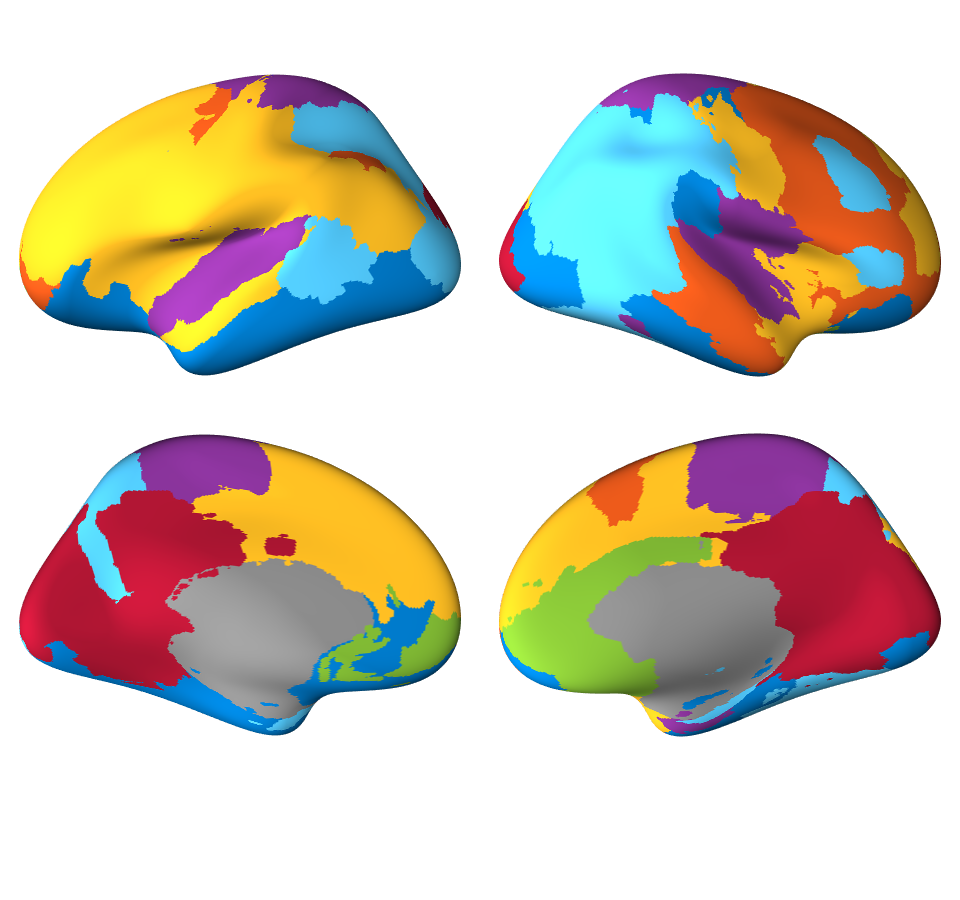

Cluster_surf uses a type of surface rendering with cluster_surf that is deprecated
It still functions, but the new method based on isocolors is dramatically faster


Cluster_surf uses a type of surface rendering with cluster_surf that is deprecated
It still functions, but the new method based on isocolors is dramatically faster


figure;
brain_activations_wani_jj(r_new, 'surface_only', 'surface_all', 'color', mat2cell(cols(u_CAPS_comm,:), ones(numel(u_CAPS_comm),1), 3));

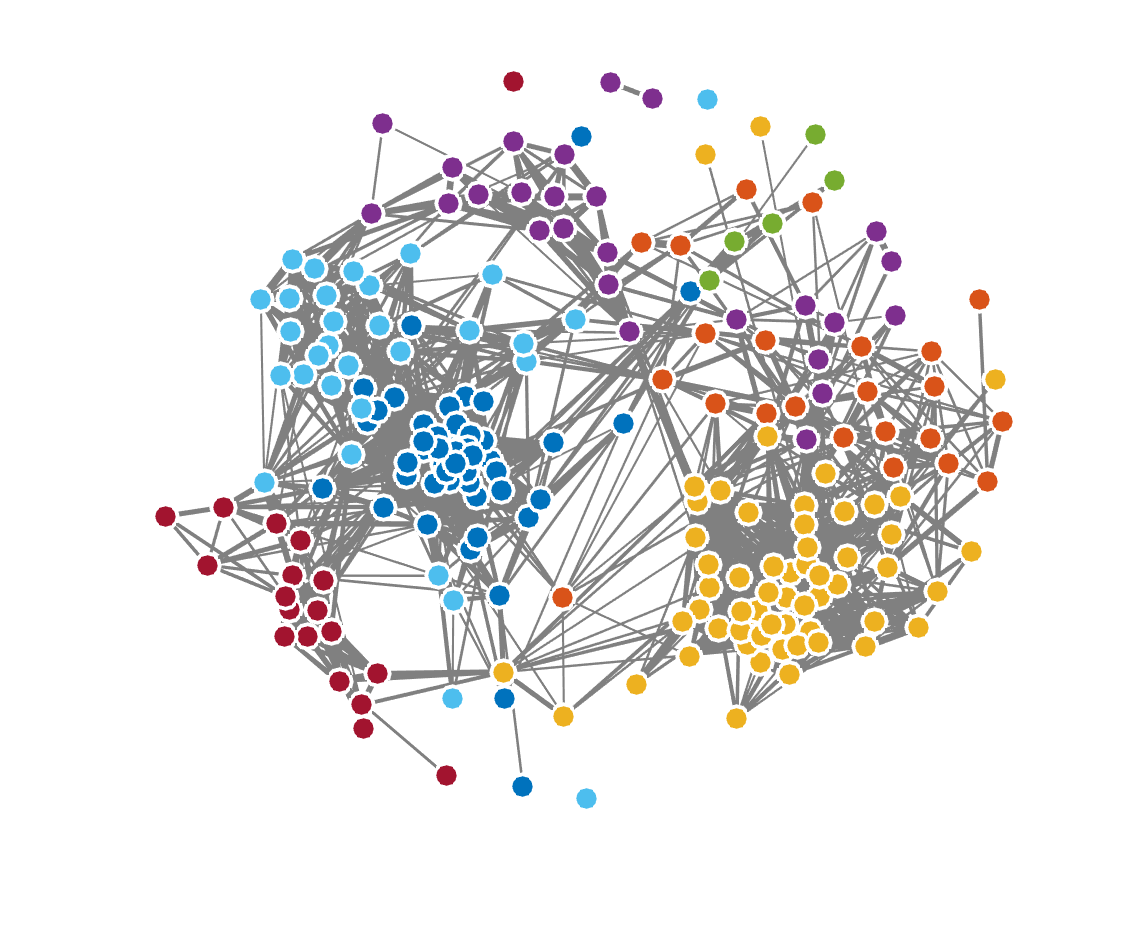

figure;
vis_network(CAPS_thr_z2o_r, 'group', CAPS_N.community_index, 'groupcolor', cols, ...
    'weighted', 'gravity', 'line_pos_color', [0.5 0.5 0.5 0.3], 'xystart', D_comp);

r = region2imagevec(atlas_info.cluster_Fan_Net.r_2mm(1:210));
r_new = r;
u_REST_comm = unique(REST_N.community_index)';
for net_i = u_REST_comm
    r_new.dat(ismember(r.dat, find(REST_N.community_index == net_i))) = net_i;
end
r_new = region(r_new, 'unique_mask_values');

Grouping voxels with unique mask values, assuming integer-valued mask:   8 regions


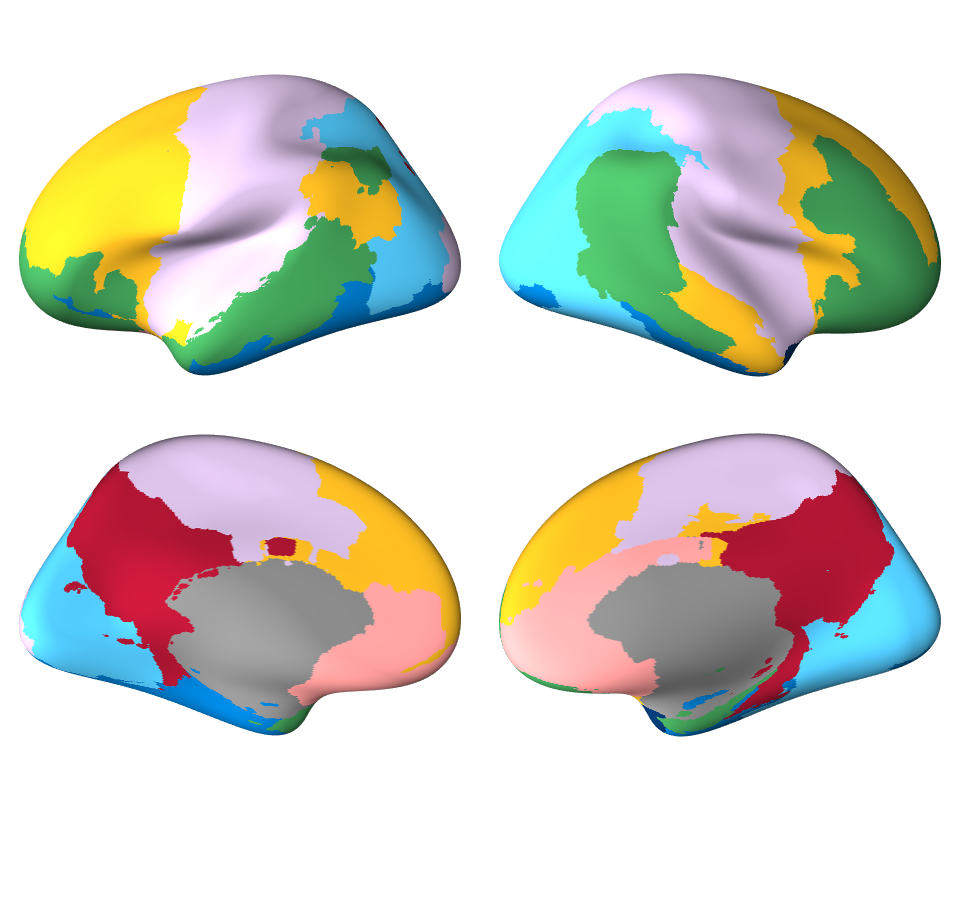

Cluster_surf uses a type of surface rendering with cluster_surf that is deprecated
It still functions, but the new method based on isocolors is dramatically faster


Cluster_surf uses a type of surface rendering with cluster_surf that is deprecated
It still functions, but the new method based on isocolors is dramatically faster


figure;
brain_activations_wani_jj(r_new, 'surface_only', 'surface_all', 'color', mat2cell(cols(u_REST_comm,:), ones(numel(u_REST_comm),1), 3));

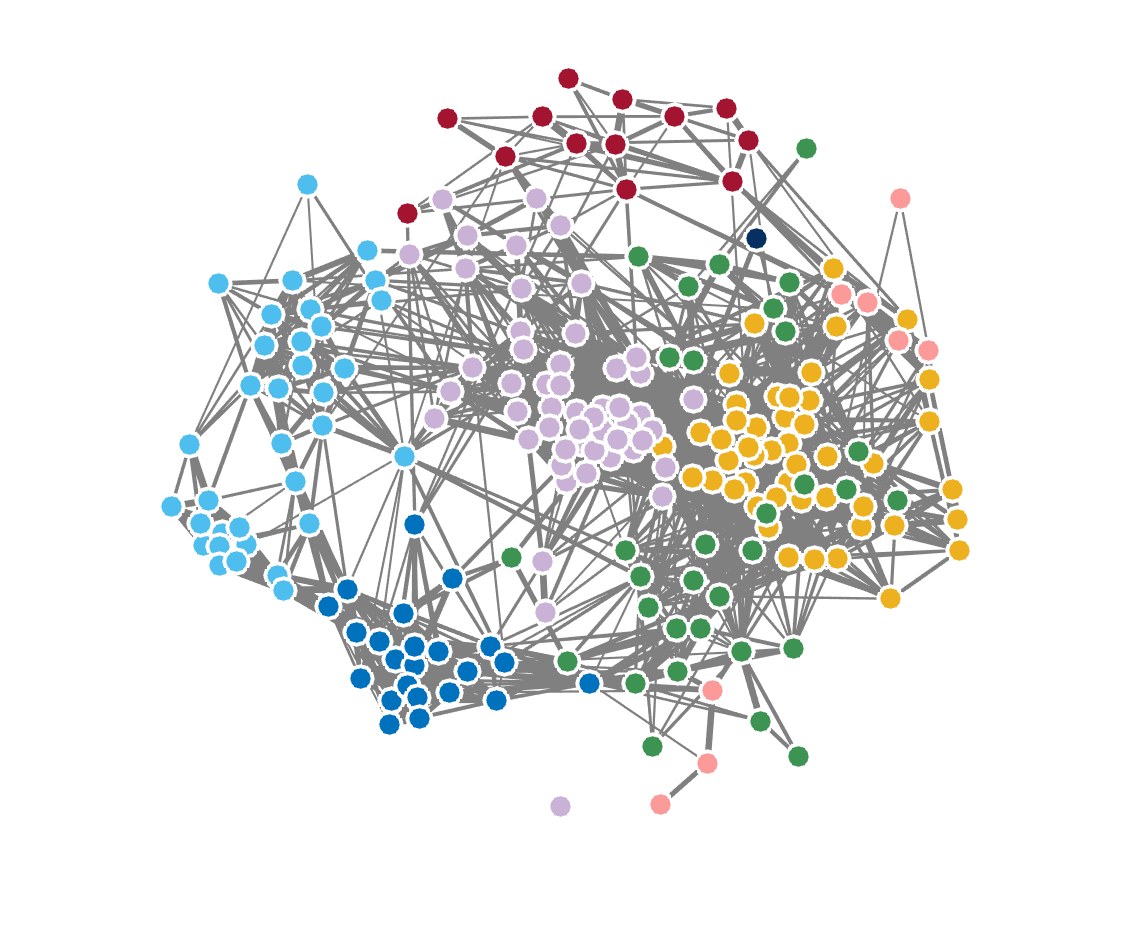

figure;
vis_network(REST_thr_z2o_r, 'group', REST_N.community_index, 'groupcolor', cols, ...
    'weighted', 'gravity', 'line_pos_color', [0.5 0.5 0.5 0.3], 'xystart', D_comp);

## Multi-layer community detection

gldir = '/Users/jaejoonglee/github/GenLouvain';
addpath(genpath(gldir));
sj_num = 18;
n_div = 3;
n_vol = size(CAPS_roi_meants{sj_num}, 1);
for div_i = 1:n_div
    wh_div = ceil((div_i-1)*n_vol/n_div + 1 : div_i*n_vol/n_div);
    CAPS_div_r{div_i} = corr(CAPS_roi_meants{sj_num}(wh_div,1:210));
    CAPS_div_thr_r{div_i} = threshold_proportional(CAPS_div_r{div_i}, 0.1);
end
N = multilayer_community_detection_individual(CAPS_div_thr_r, 'ord');

Multilayer community detection ... 
Working on SUBJECT 001 ... 


Grouping voxels with unique mask values, assuming integer-valued mask:   4 regions


Cluster_surf uses a type of surface rendering with cluster_surf that is deprecated
It still functions, but the new method based on isocolors is dramatically faster


Cluster_surf uses a type of surface rendering with cluster_surf that is deprecated
It still functions, but the new method based on isocolors is dramatically faster


Grouping voxels with unique mask values, assuming integer-valued mask:   4 regions


Cluster_surf uses a type of surface rendering with cluster_surf that is deprecated
It still functions, but the new method based on isocolors is dramatically faster


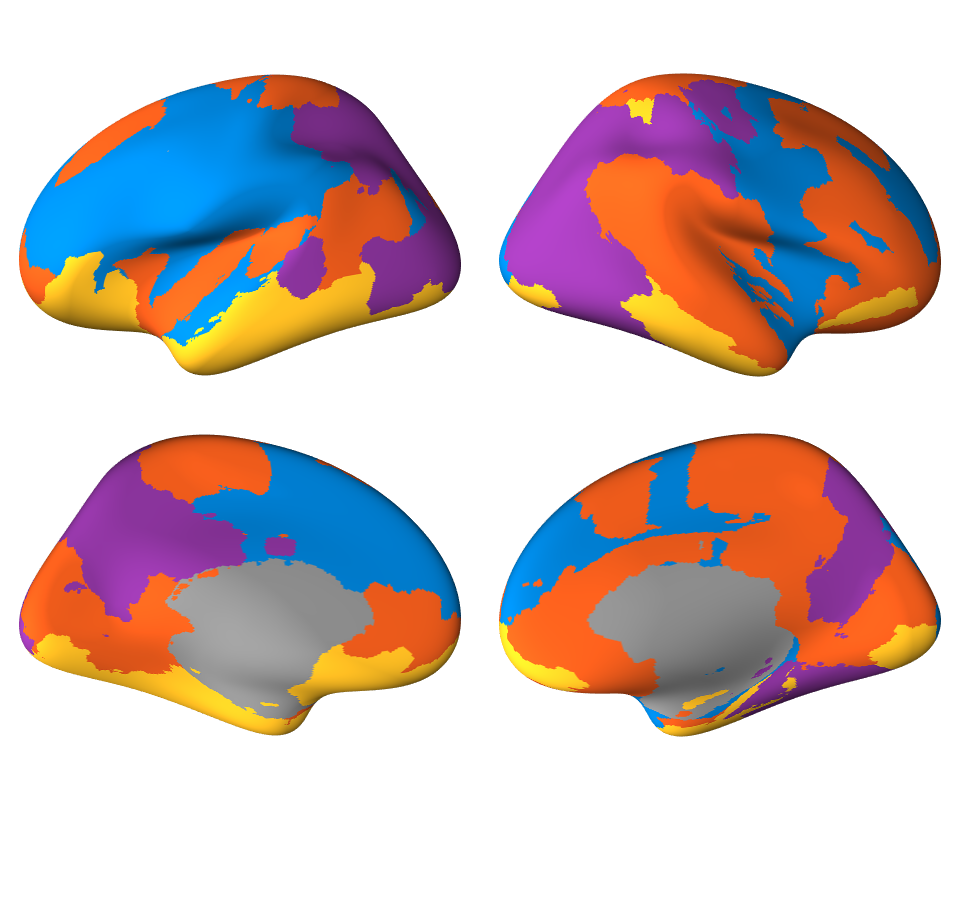

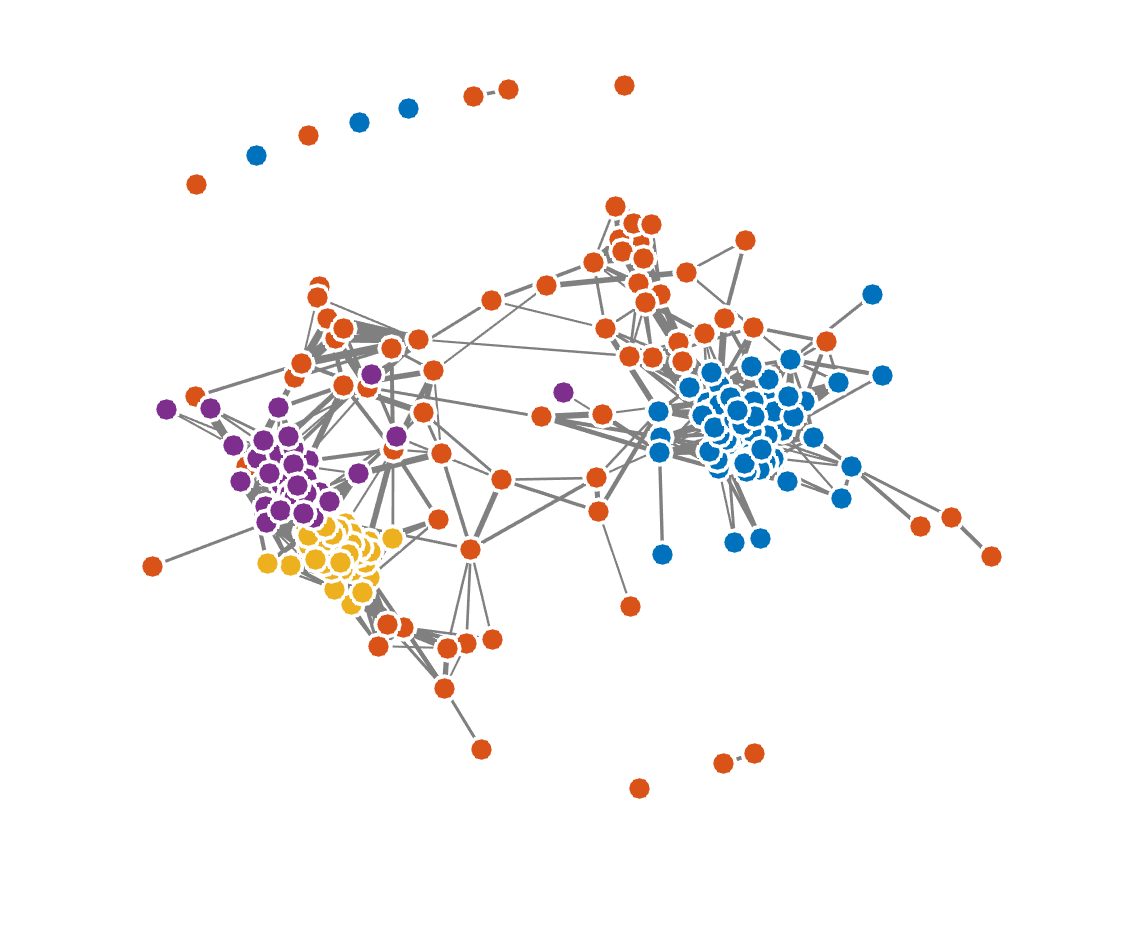

Cluster_surf uses a type of surface rendering with cluster_surf that is deprecated
It still functions, but the new method based on isocolors is dramatically faster


Grouping voxels with unique mask values, assuming integer-valued mask:   4 regions


Cluster_surf uses a type of surface rendering with cluster_surf that is deprecated
It still functions, but the new method based on isocolors is dramatically faster


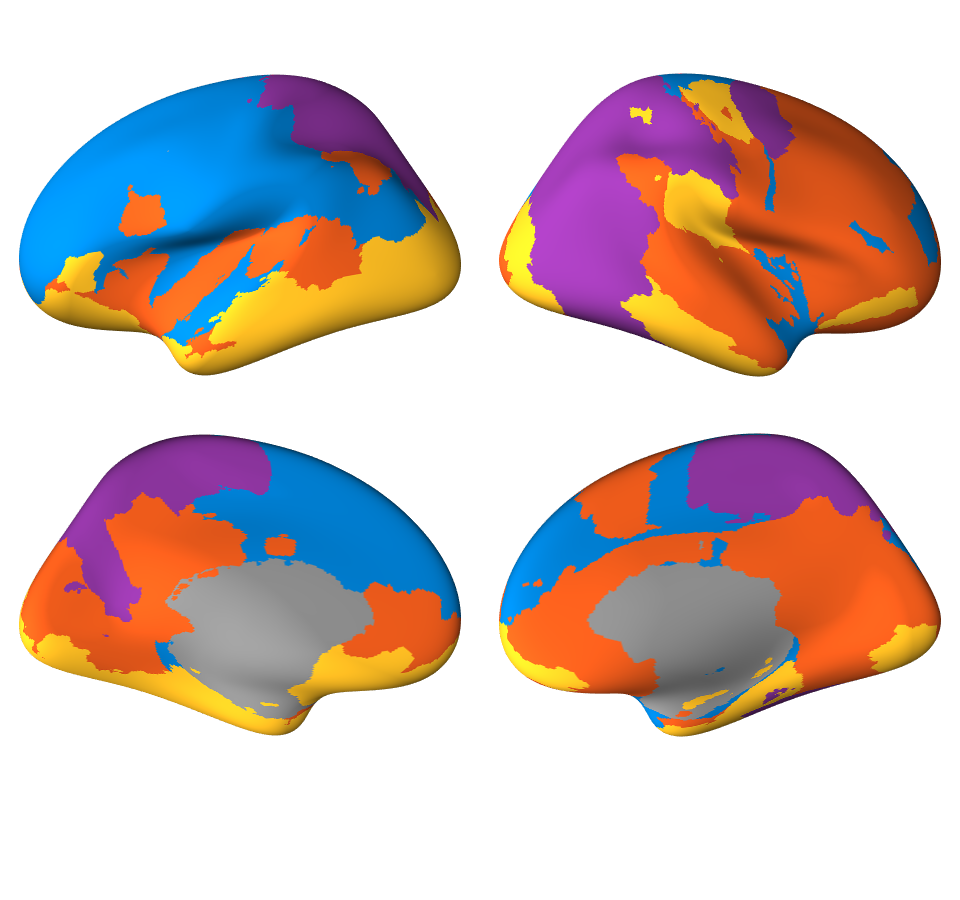

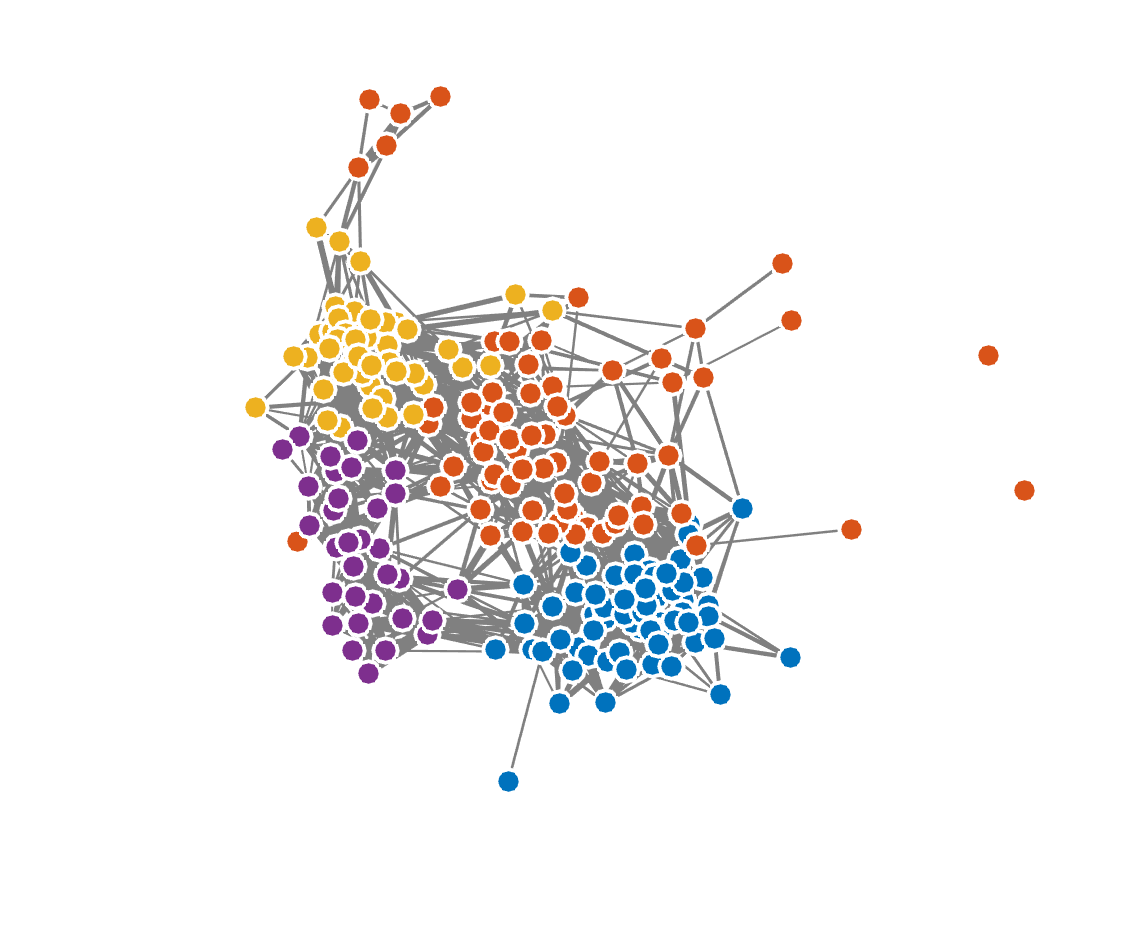

Cluster_surf uses a type of surface rendering with cluster_surf that is deprecated
It still functions, but the new method based on isocolors is dramatically faster


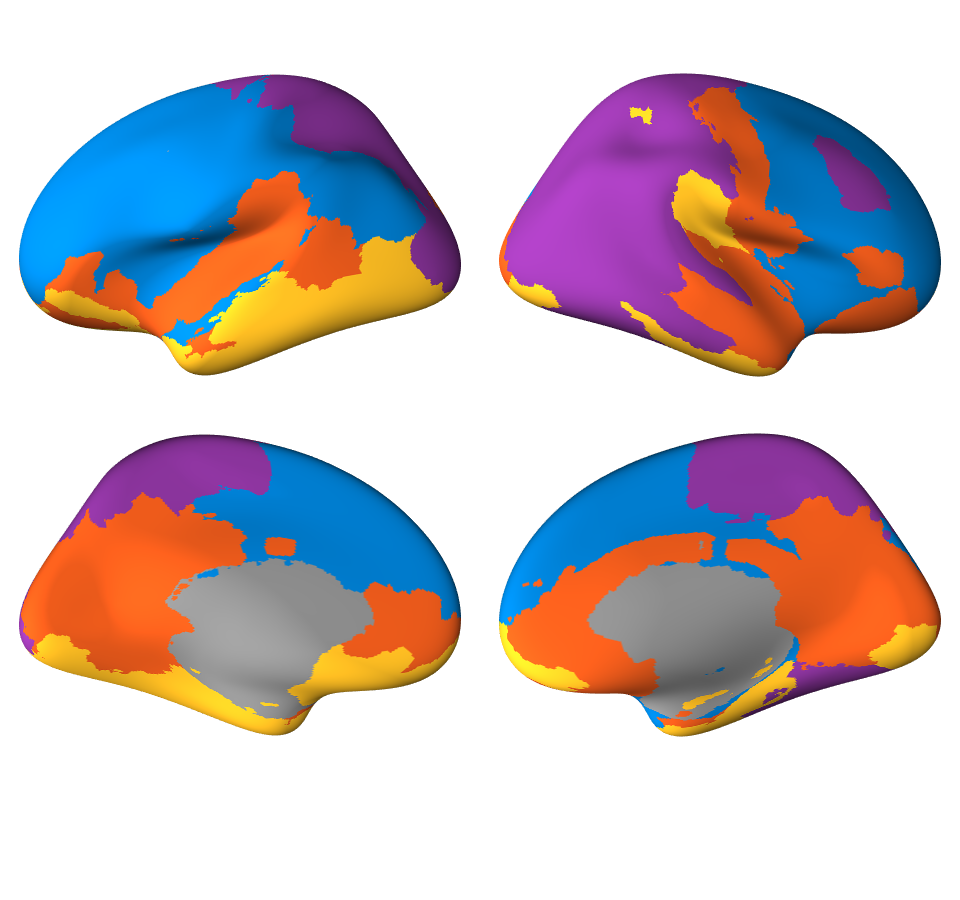

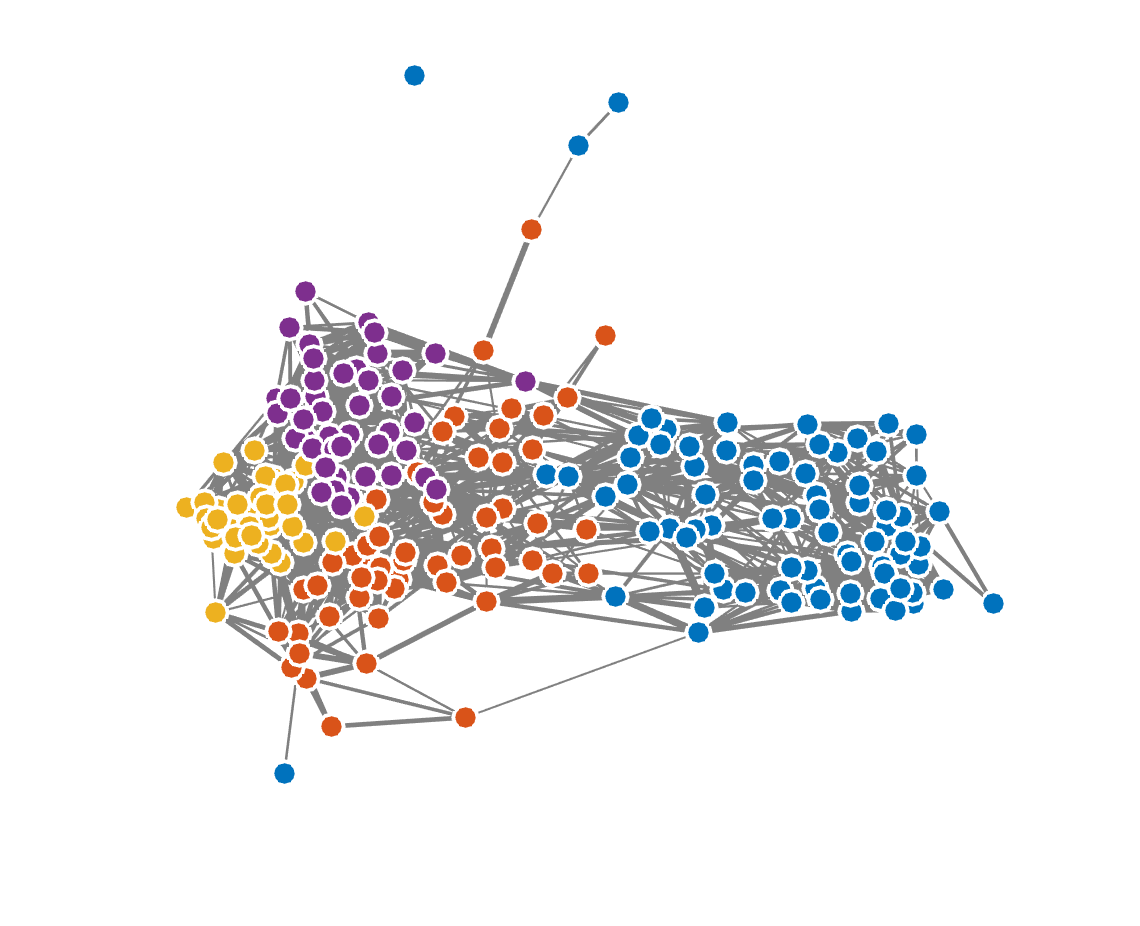

for div_i = 1:n_div
    r = region2imagevec(atlas_info.cluster_Fan_Net.r_2mm(1:210));
    r_new = r;
    u_CAPS_comm = unique(N{1}.multi_module_consensus_sorted(:,div_i))';
    for net_i = u_CAPS_comm
        r_new.dat(ismember(r.dat, find(N{1}.multi_module_consensus_sorted(:,div_i) == net_i))) = net_i;
    end
    r_new = region(r_new, 'unique_mask_values');
    figure;
    brain_activations_wani_jj(r_new, 'surface_only', 'surface_all', 'color', mat2cell(cols(u_CAPS_comm,:), ones(numel(u_CAPS_comm),1), 3));
    figure;
    vis_network(CAPS_div_thr_r{div_i}, 'group', N{1}.multi_module_consensus_sorted(:,div_i), 'groupcolor', cols, ...
        'weighted', 'gravity', 'line_pos_color', [0.5 0.5 0.5 0.3], 'xystart', D_comp);
end